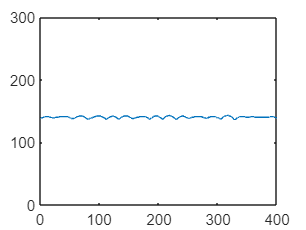

clear all

threshold=0;

%biomass_3500_0(1:400,1:400)=0.0;
run('biomass_at4200_D10000.m')

interface_Xcoordinate(1:400)=1;

for x=2:400
    for y=1:400
        if abs(biomass_4200_0(x-1,y)-biomass_4200_0(x,y))>threshold
            interface_Xcoordinate(y)=x;
        end
    end
end

plot(interface_Xcoordinate(:));
ylim([0,300])

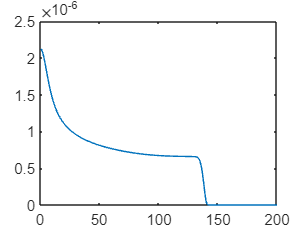



for x=1:400
    biomass(x)=0.0;
    for y=1:400
        biomass(x)=biomass(x)+biomass_4200_0(x,y)/400;
    end
end

plot(biomass(1:200));



Roughness=std(interface_Xcoordinate)

Roughness = 1.4287

R(1)=Roughness

R = 1.4287

PS=fft(interface_Xcoordinate(:))

PS = 1.0e+04 *

   5.6038 + 0.0000i
   0.0005 + 0.0009i
   0.0013 - 0.0001i
  -0.0002 + 0.0006i
  -0.0006 - 0.0006i
  -0.0018 + 0.0002i
  -0.0003 - 0.0009i
  -0.0026 + 0.0018i
   0.0018 - 0.0018i
   0.0037 - 0.0010i


Xs=0.01 %cm

Xs = 0.0100

Ks=1/0.01 %1/cm

Ks = 100

k = (0:length(PS)-1)*Ks/length(PS);
f=figure()

f =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 242 560 420]
       Units: 'pixels'

  Show all properties


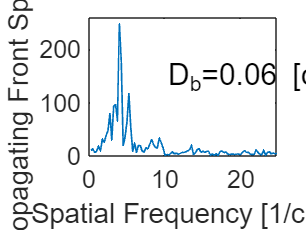

plot(k(2:100),abs(PS(2:100)),'LineWidth',1)
ylim([0 260])
xlabel('Spatial Frequency [1/cm]','FontSize',18)
ylabel('Propagating Front Spectrum','FontSize',18)
text(10,150,'D_b=0.06 [cm^2/g·s]','FontSize',18)
%set(tx,'Interpreter','latex');
exportgraphics(f,'PS_D10000.png')
set(gca,'FontSize',15)